## Lab 3, Part 1: Deep Convolutional Networks for Image Recognition and Object Detection

### 1.1 Introduction

- The objective of this laboratory is to learn about deep convolutional networks used in computer vision applications, specifically image recognition and object detection here.

- For related background reading to this lab, you can check the Lecture 5 & 6 notes/slides on Blackboard and [Chapter 9](https://www.deeplearningbook.org/contents/convnets.html), of the book Deep Learning (Goodfellow, Bengio and Courville, 2016).

- You will need the Deep Learning Toolbox, and Statistics and Machine Learning Toolbox installed.

- **You will need to download the image data folder Caltech101_Reduced.zip using the link on Blackboard and save the unzipped folder into your working directory with this lab file (as well as the boundingBoxData.mat file). It can take a long time to unzip files on University computers so you could do the Python part of the lab whilst waiting for files to unzip. **

### 1.2 Problem description

The data used in this lab is based on the Caltech101 dataset, which is a collection of images with categorisation labels and bounding boxes - in the lab I have reduced the data down to just 4 classes to make the data more tractable for this learning exercise (the classes are airplane, ferry, helicopter and motorbike). 

The tasks are divided down into two parts:

- Image recogniton, i.e. a classification task 

- Object detection, i.e. a regression task, where the system predicts the bounding box around the object in the image. For this lab we just use the bounding boxes for the helicopter class.

### 1.3 Methods

**Data**

In this lab the problem is based on image recognition and object detection; the input data $\mathbf{x}$ is an image and the output data $\mathbf{y}$ is either a class label (there are 4 classes: airplane, ferry, helicopter and motorbike), or bounding box coordinates defining the location of the object within the image where there are 4 values defining the bounding box: [left bottom width height]

**Model**

The model for classification predicts the probabilty of a given class (airplane, ferry, helicopter or motorbike) and for object detection predicts bounding box coordinates: both are based on a deep convolutional network and only the output layer is different between the two,


$$\hat{\mathbf{y}} = f\left(\phi( \mathbf{x}); \mathbf{ \theta} \right)$$


where $\hat{\mathbf{y}}$ contains the prediction of the model: and the function $f$ is a linear-to-softmax for classification or just a linear output for regression; for notational convenience we represent all model parameters in a vector $\mathbf{\theta}$, which comprises all the model parameters.

The function $\phi( \mathbf{x})$ performs feature extraction on the input $\mathbf{x}$ and is constructed from layers of simple functions, mainly convolutional functions here,


$$z_{i,j,k}^{(l)} = \sum_{c}^{}{\sum_{m}^{}{\sum_{n}^{}{w_{m,n,c,k}^{(l)}x_{i + m,j + n,c}^{(l - 1)} + b_{k}^{(l)}}}} \quad \text{for} \quad k = 1,\ldots,N_{F}$$


where $N_F$ is the number of convolutional filters.  Note that whilst this function may appear complicated, it is still based on the basic affine transformation $wx+b$, and so is similarly simple and comparable to a fully connected layer. The convolutional layer output $z_{i,j,k}^{(l)} $ undergoes transformation by a nonlinear activation function to add nonlinearity to the model,


$$x_{i,j,k}^{(l)} = h\left( z_{i,j,k}^{(l)} \right)$$


The convolutional layers can be combined with other layers to build a full model, such as batch normalisation layers, fully connected layers and dropout layers.

**Loss function**

The loss function,$J\left(\theta \;\right)$, that we minimise to estimate the model parameters, $\theta$, is based on the negative log-liklihood for both classification and regression, meaning we minimise the categorical cross-entropy for classification,


$$J\left(\theta \;\right)=-\sum_{j=1}^m \sum_{k=1}^K y_{j,k} \;\log \;{\hat{y} }_{j,k} \;$$


where the number of classes $K$ and the number of input-output data pairs is $m$, whilst the loss function for bounding box regression is the squared error,

 
$$J\left(\theta \;\right)=\sum_{j=1}^m \sum_{k=1}^K {\left({\hat{y\;} }_{j,k} -y_{j,k} \right)}_{\;}^{\;2} =\sum_{j=1}^m \sum_{k=1}^K e_{j,k\;}^{\;2}$$


where the number of regression outputs is $K$ (i.e. the four coordinates defining the bounding box in this case, so $K=4$).

**Parameter estimation algorithm**

The parameter estimation algorithm here is based on the Adam algorithm, which combines a momemtum-like term, $v_{j}$, with an adaptive learning rate, $r_{j}$, and bias corrected versions of these terms, $\hat{v}_j$ and $\hat{r}_j$, where the j-th parameter update is


$$\theta_{j} \leftarrow \theta_{j} - \frac{\epsilon}{\sqrt{\hat{r}_{j}}} \hat{v}_{j}$$


where $\epsilon $  is a learning rate and


$$ \hat{r}_j = \frac{r_{j}}{1- \beta_1^t} \\
    \hat{v}_j = \frac{v_{j}}{1- \beta_2^t} \\
    v_{j} \leftarrow \beta_1 v_{j} + \left( 1 - \beta_1 \right)g_{j} \\
    r_{j} \leftarrow \beta_2 r_{j} + \left( 1 - \beta_2 \right)g_{j}^{2}  $$


and $g_j$ is the stochastic estimate of the loss function gradient for parameter $j$,


$$ g_{j} = \nabla_{{\theta}} \hat{J}(\theta_j)$$


and $ g_{j}$ is the estimate of the gradient of the loss function $\nabla_{{\theta}} \hat{J}({\theta})$, which is obtained from a mini-batch of data via automatic differentiation.

### 1.4 Deep convolutional network for image recognition

#### 1.4.1 Load and pre-process data

Create an image data store from the folders of raw images, where the image is the input $\mathit{\mathbf{x}}$ and the output $y$ is the class label, which is created from the folder name, i.e. airplane, ferry, helicopter, motorbike.

clear all

% initialise the random number generator seed for repeatable results
rng(1,'twister');

% create an image data store from the raw images 
imds = imageDatastore('Caltech101_Reduced',...
"IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../Deep Learning/LAB 2/Caltech101_Reduced/airplane/image_0001.jpg';
                              ' .../Deep Learning/LAB 2/Caltech101_Reduced/airplane/image_0002.jpg';
                              ' .../Deep Learning/LAB 2/Caltech101_Reduced/airplane/image_0003.jpg'
                               ... and 257 more
                              }
                     Folders: {
                              ' .../Documents/Autonomous Systems/Deep Learning/LAB 2/Caltech101_Reduced'
                              }
                      Labels: [airplane; airplane; airplane ... and 257 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                 

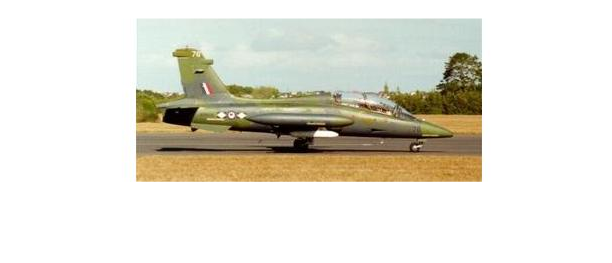

% This line of code is written in MATLAB and it creates an ImageDatastore object named "imds". 
% ImageDatastore is a type of object in MATLAB used to store and manage collections of image data.

% In MATLAB, the ellipsis (...) is used as a line continuation operator. It allows you to break a 
% long line of code into multiple lines for readability without affecting the functionality of the code.

% The first argument, 'Caltech101_Reduced', specifies the location of the image data.

% IncludeSubfolders, true - This is an option for the imageDatastore function. 
% Setting it to true indicates that the function should include images from subfolders 
% within the specified folder ('Caltech101_Reduced'). 

%% display sample image
figure;
imshow(preview(imds)); 

% imshow(preview(imds));, it displays a preview of the first few images in the ImageDatastore.

Split data into training, and validation sets. 

% create randomised training, validation and test sets of data
imds = shuffle(imds);
[imdsTrain, imdsVal] = splitEachLabel(imds, 0.7);

To train a network and make predictions on new data, the images must all be the same size and match the input size of the network. If you need to adjust the size of your images to match the network, then you can rescale or crop data to the required size. To avoid re-saving all the images to a different size or format, we can use an `augmentedImageDatastore` to resize and convert any grayscale images to RGB on-the-fly. The `augmentedImageDatastore` can be used for additional data augmentation as well when used for network training.

% use the transform function to resize each image
image_size = [224 224];
dsTrain = augmentedImageDatastore(image_size, imdsTrain, 'ColorPreprocessing', 'gray2rgb');
dsVal = augmentedImageDatastore(image_size, imdsVal,'ColorPreprocessing', 'gray2rgb');

#### 1.4.2 Design the deep convolutional network

Design the deep convolutional network model for image recognition (i.e. classifying the images - note there are 4 images classes here: airplane, ferry, helicopter, motorbike).

The network is constructed from different types of layer (simple functions): 

- convolutional layers, 

- batch normalization layers, 

- rectified linear unit activation functions, 

- max pooling layers, 

- dropout layer,

- fully connected layers and 

- a softmax layer at the output.

The convolutional layers usually occur in blocks of conv -> batchnorm -> relu. A max pool is used to reduce feature map size in between conv blocks.

**Task: The code block below sets up a deep convolutional network but the convolutional blocks are missing! Add 2 blocks of conv -> batchnorm -> relu -> maxpool layers as shown below in between the input layer and the dropout layer, **

- convolution2dLayer(filter_size,num_filters,'Padding','same')

- batchNormalizationLayer

- reluLayer

- maxPooling2dLayer(2,'Stride',2)

then evaluate the network performance (the validation accuracy score is needed for the quiz).

% define constant parameters
num_classes = 4;  % number of classes
num_filters = 8;  % base number of filters in convolutional layers
filter_size = 3;  % convolutional filter size

% define network layers
layers = [
    imageInputLayer([image_size 3])

    convolution2dLayer(filter_size, num_filters, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(filter_size, num_filters, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    dropoutLayer(0.2)

    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer
    ];

% display network design
analyzeNetwork(layers)

#### 1.4.3 Train the network 

We will train the network with the Adam algorithm.

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       18.75% |       42.11% |       1.6895 |       5.5911 |          0.0010 |
|       1 |          10 |       00:00:06 |       75.00% |       61.84% |       1.2929 |       2.5376 |          0.0010 |
|       2 |          20 |       00:00:09 |      100.00% |       81.58% |       0.0089 |       1.3812 |          0.0010 |
|       3 |          30 |       00:00:11 |      100.00% |       81.58% |       0.0242 |       1.2698 |          0.

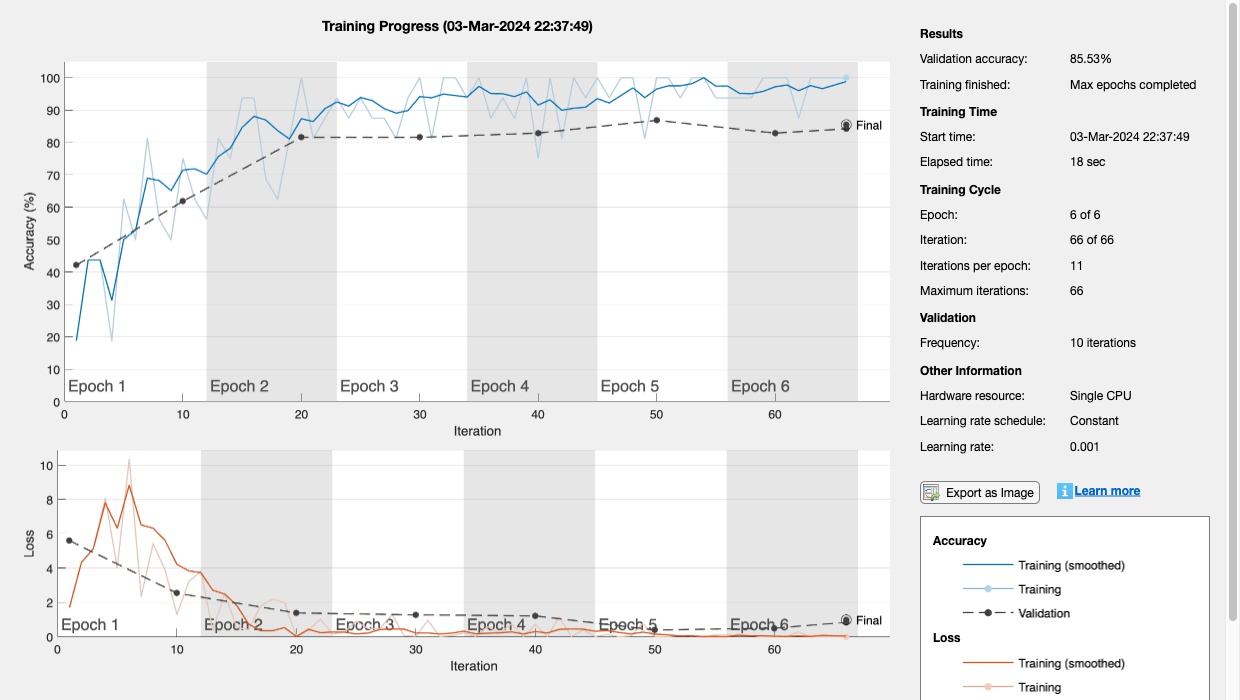

% training options 
options = trainingOptions('adam', ...
    "MiniBatchSize",16, ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',6, ...
    'Shuffle','every-epoch', ...
    'ValidationData',dsVal, ...
    'ValidationFrequency',10, ...
    'Verbose',true, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','cpu');

% train network
net = trainNetwork(dsTrain,layers,options);

#### 1.4.4 Evaluate the image recognition system

Evaluate the accuracy of the image recognition system on the test data

% classify the validation output using the trained network
[YPred, probs] = classify(net, dsVal);

% extract ground truth labels
YVal = imdsVal.Labels;

% accuracy in percent
accuracy = 100*sum(YPred == YVal)/numel(YVal);
disp(['The accuracy is: ' num2str(accuracy)])

The accuracy is: 85.5263


Plot a confusion matrix to further evaluate the image recognition system. Look for off-diagonal terms that indicate a confusion in the system - i.e. mis-classifications and think about where they occur and why they occur.

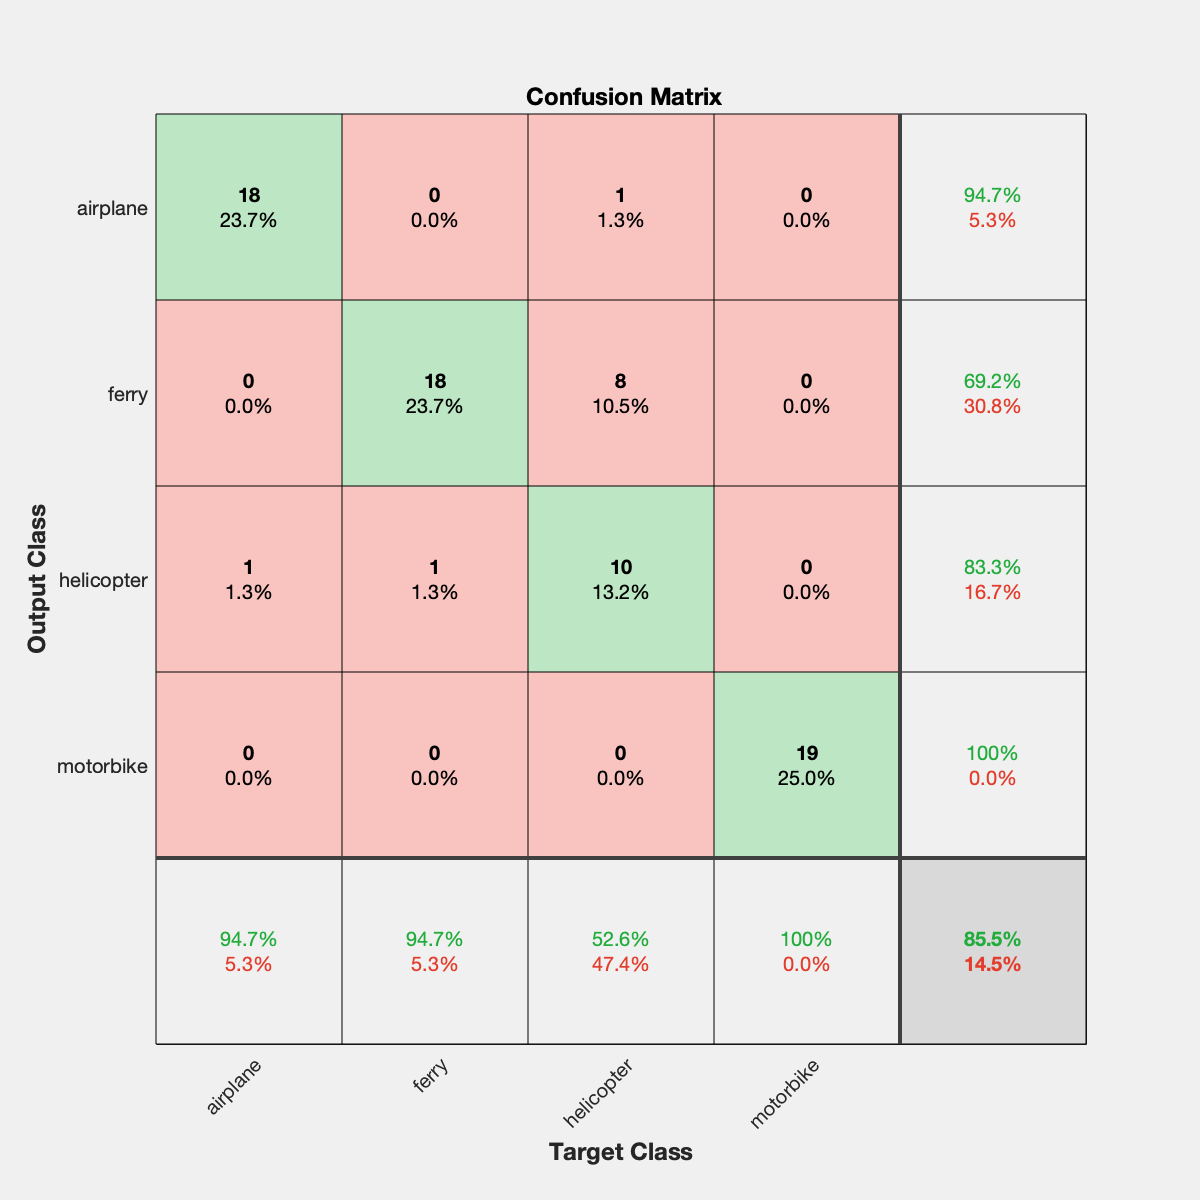

% plot confusion matrix
figure;
plotconfusion(YVal,YPred)


disp(["Validation Set Accuracy: " num2str(accuracy) "%"]);

    "Validation Set Accuracy: "    "85.5263"    "%"



Check out the confusion matrix: notice that helicopter and ferry are often confused with each other. Why might this be? (Maybe because they both often occur on a blue background etc.)

Now display validation images to check model behaviour

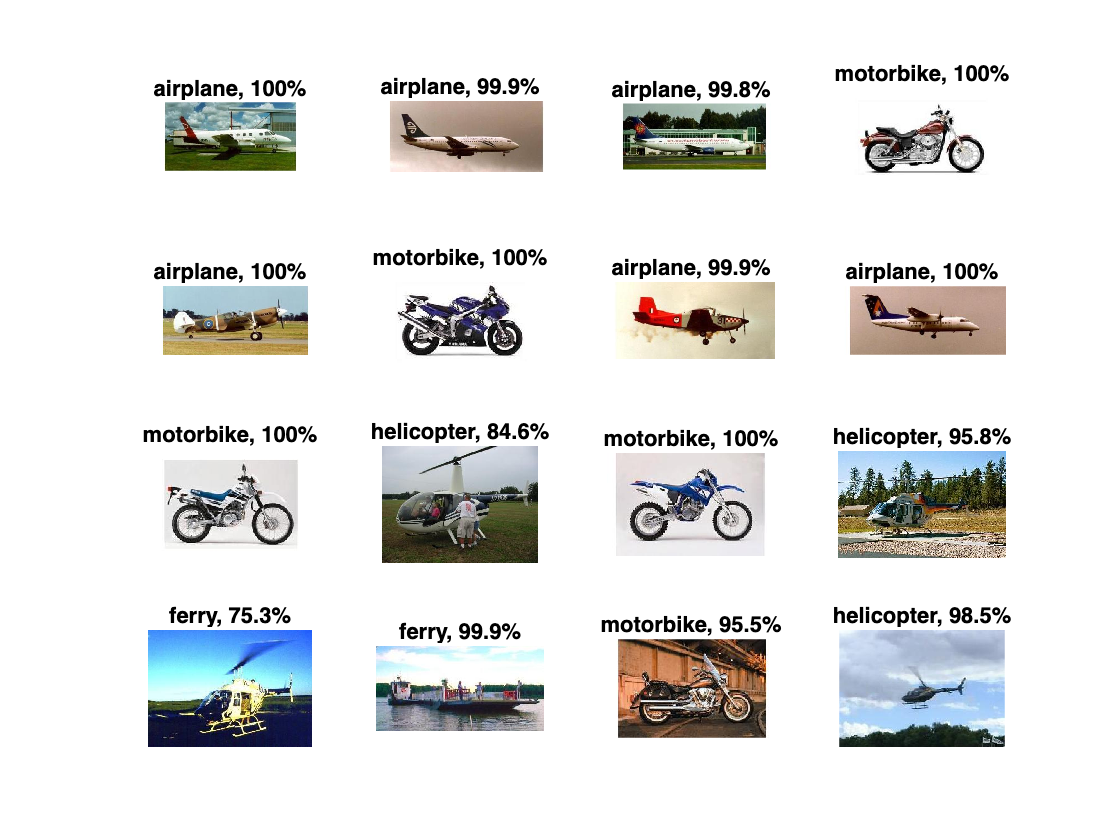

% Display sample test images with predicted labels and
% the predicted probabilities of the images having those labels.
idx = randperm(numel(imdsVal.Files), 16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsVal,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label)+ ", "+num2str(100*max(probs(idx(i),:)),3)+"%");
end

Inspect the image recognition results - you might notice that occasionally ferries and helicopters are confused with each other. Note that the system has high accuracy on training data but lower accuracy on validation data, this implies that:

- the system has sufficient model capacity because it achieves very high accuracy on the training data, evidencing that the system is capable of recognising all images (so there is no need to change the model structure);

- the system is overfitting to the training data because of the gap in training data accuracy and validation data accuracy.

The main action you can take to improve accuracy when overfitting is to collect more data, or use some (additional) type of regularisation strategy, e.g. a data augmentation technique. 

That's the end of the image recognition part.

### 1.5 Deep convolutional network for object detection

This section implements, trains and evaluates a deep convolutional network for object detection.

#### 1.5.1 Load data 

Load and pre-process data - this section does the following: 

- reads the bounding box annotations for the helicopter images and from these creates a Table to store these in Matlab, denonted T

- creates a box label data store from the table T

- combines the images with the corresponding bounding boxes into a single datastore using the 'combine' function

- plots an example image with bounding box overlay to check everything is working correctly

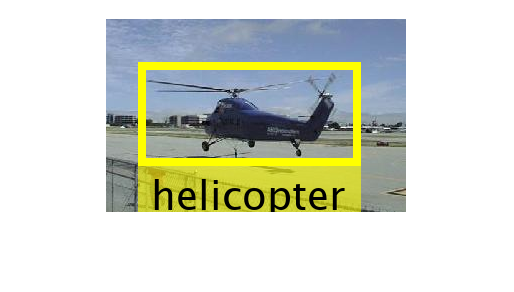

% data pre-processing

% clear all previous data
clear all

% load bounding box data for helicopter class 
load boundingBoxData.mat;

% store bounding box data in a table T
T = boundingBoxData;

% box label data store
blds = boxLabelDatastore(T);

% image store
imds = imageDatastore('Caltech101_Reduced/helicopter');

% combine labels and images into single data store
cds = combine(imds, blds);

% check combined data store by previewing an image with bounding box
figure
for i = 1:1

    % read data and display
    data = read(cds);
    I = data{1};
    bbox = data{2};
    label = {'helicopter'};

    % Display the image and box label data.
    annotatedImage = insertObjectAnnotation(I,'rectangle',bbox,label, ...
        'LineWidth',8,'FontSize',40);
    imshow(annotatedImage)

    drawnow

end

#### 1.5.2 Pre-process data and split into training and validation sets

Split the data into training and validation sets - the important thing to note here is that you have to operate on the original image data store defined above, imds, and the original table T containing the bounding boxes (because Matlab does not let you split the combined data we created above cds).

Also note that whilst Matlab has a nice function for splitting classification data that we used above 'splitEachLabel', the problem here is regression so splitEachLabel will not work therefore we have to split the data manually. 

% image training and validation split
imdsTrain = imageDatastore(imds.Files(1:50));
imdsVal = imageDatastore(imds.Files(51:65));

% bound box training and validation split
bldsTrain = boxLabelDatastore(T(1:50,:));
bldsVal = boxLabelDatastore(T(51:65,:));

% combine labels and images into single data store
cdsTrain = combine(imdsTrain,bldsTrain);
cdsVal = combine(imdsVal,bldsVal);

To train a network and make predictions on new data, the images must all be the same size and match the input size of the network. This next section resizes both the image AND the bounding box to a standard, custom size.

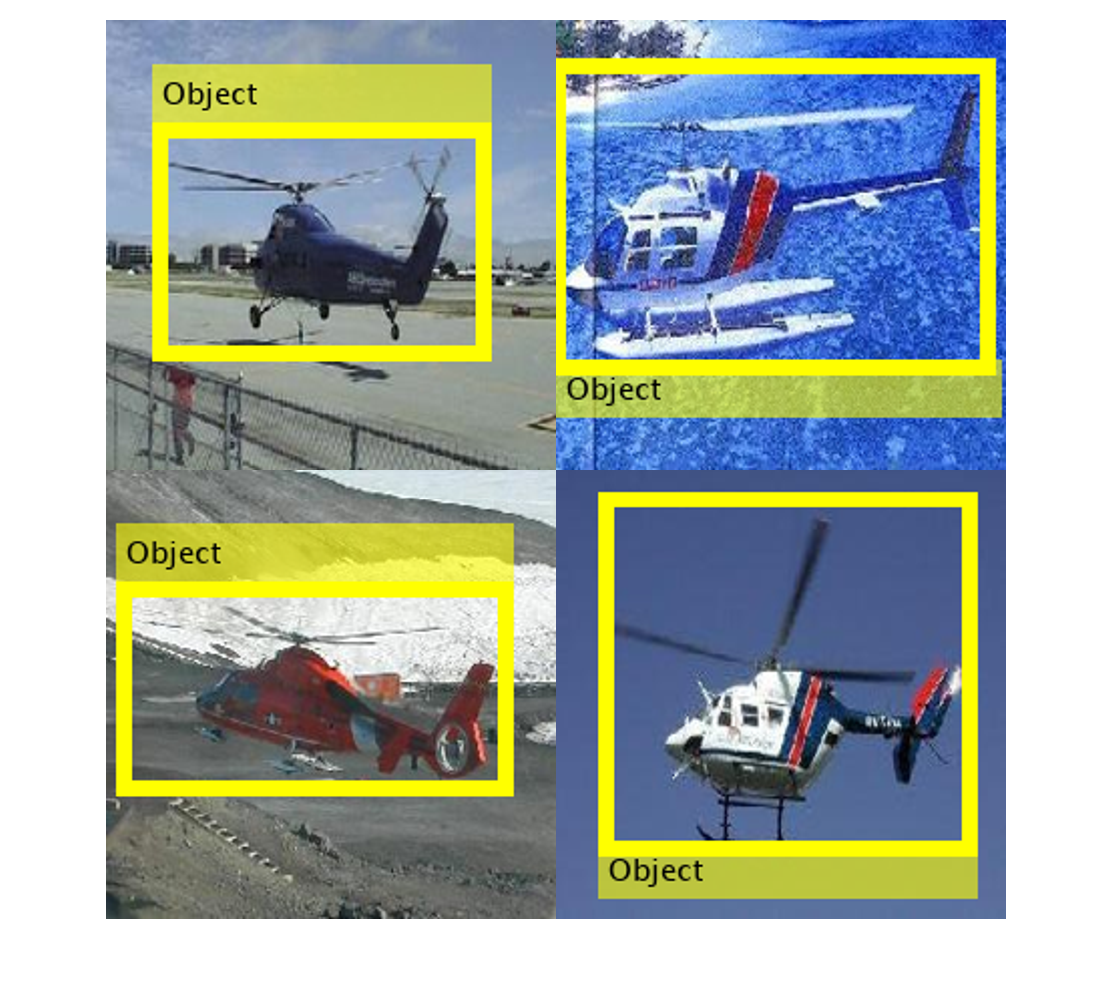

% input image size
image_size = [224 224];

% transform the images and bounding boxes to the input image size
preprocessedTrainingData = transform(cdsTrain,...
    @(data)resizeImageAndLabel(data,image_size));

% preprocess validation data
preprocessedValidationData = transform(cdsVal,...
    @(data)resizeImageAndLabel(data,image_size));

% Read all of the preprocessed data
data = readall(preprocessedTrainingData);

% Display the preprocessed image and box label data
figure;
numObservations = 65;
rgb = cell(4,1); 
for k = 1:4
    I = data{k,1};
    bbox = data{k,2};
    labels = 'Object';
    rgb{k} = insertObjectAnnotation(I,'rectangle',bbox,labels, ...
        'LineWidth',8,'FontSize',15);
end
montage(rgb)

#### 1.5.3 Design deep convolutional network for object detection

Design the deep convolutional network model for object detection (i.e. predicting the bounding box around the image - note there are 4 outputs to define the bounding box: the 4 coordinates for left, bottom, width, height).

**Task: You need to construct the layers for the network in the layers line of code below. You can use exactly the same type of feature extraction as for the image recognition network above and just change the output type (i.e. you can basically copy/paste the code from the image recognition section and then replace the classificationLayer with regressionLayer, delete the softmax function and replace num_classes with num_outputs - easy!). Construct the network using this structure:**

- image input layer

- conv2D(filter_size, num_filters, Padding,'same') -> batchnorm -> relu -> maxpool(2,'stride',2)

- conv2D(filter_size, num_filters, Padding,'same') -> batchnorm -> relu -> maxpool(2,'stride',2)

- dropout(0.2)

- fully connected(num_outputs)

- regression layer

Keep num_outputs, and num_filters and filter_size as defined below.

% Define constant parameters
num_outputs = 4;   % number of outputs - i.e. the number of bounding box parameters
num_filters = 32;  % base number of filters in convolutional layers
filter_size = 3;   % convolutional filter size
Padding = 'same';  % Padding type for convolutional layers

% Define the network layers
layers = [
    % Image input layer
    imageInputLayer([224 224 3])
    
    % Convolutional layer 1
    convolution2dLayer(filter_size, num_filters, 'Padding', Padding)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Convolutional layer 2
    convolution2dLayer(filter_size, num_filters, 'Padding', Padding)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Dropout layer
    dropoutLayer(0.2)
    
    % Fully connected layer
    fullyConnectedLayer(num_outputs)
    
    % Regression layer
    regressionLayer
];

% Analyze the network
analyzeNetwork(layers)


#### 1.5.4 Training 

We will train the network with the Adam algorithm.

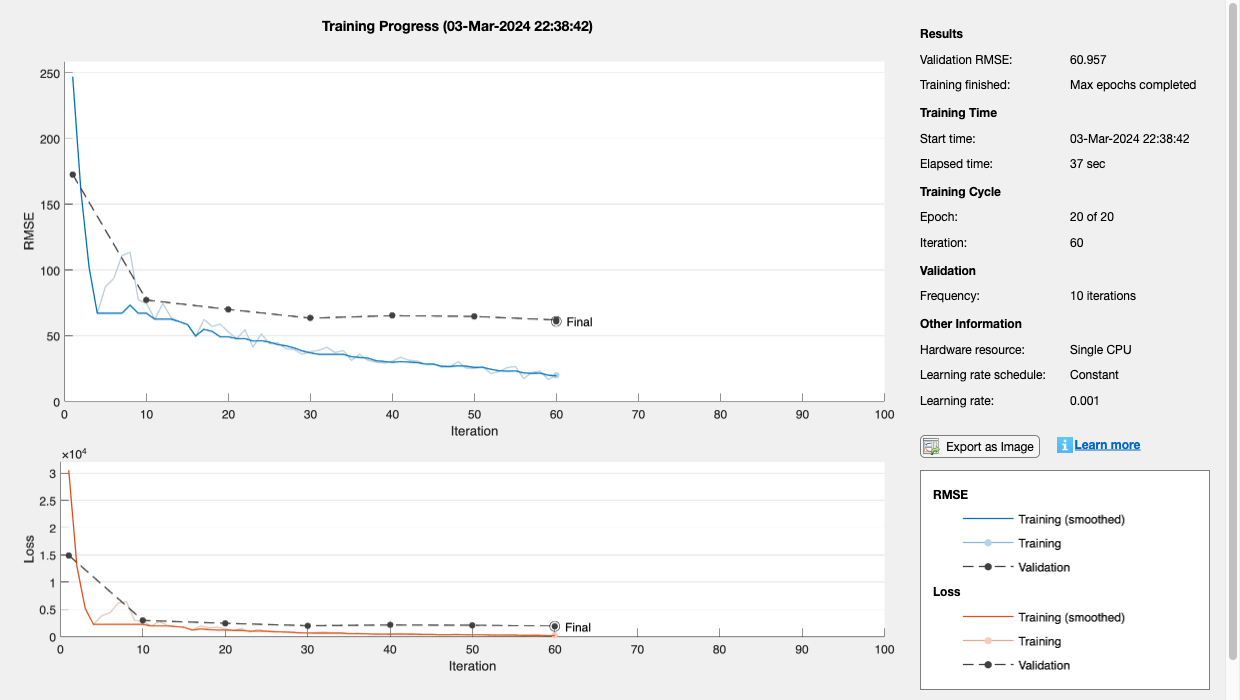

%% train network

miniBatchSize  = 16;
options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',20, ...
    'InitialLearnRate',0.001, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',preprocessedValidationData, ...
    'ValidationFrequency',10, ...
    'ExecutionEnvironment','cpu');
    
% Create the network using trainNetwork
net = trainNetwork(preprocessedTrainingData,layers,options);

Notice that there is a gap between the training data loss and the validation data loss implying that the model is overfitting. Early stopping could help prevent overfitting in this instance. Also collecting more data to train on would benefit this system.

#### 1.5.5 Test and evaluate the performance of the object recognition system 

The object detection system is evaluated here on the **Intersection over Union (IoU) metric**, which calculates the overlap between the ground truth bounding box and the predicted bounding box. Note that the IoU is a normalised metric in the range 0-1, with 0 meaning no overlap (very bad!) and 1 meaning perfect overlap (very good!).

% read validation data
data = readall(preprocessedValidationData);

% extract ground truth bounding box data from validation data
for i = 1:length(data)
    YVal(i,:) = data{i,2};
end

% predict outputs
YPred = predict(net,preprocessedValidationData);

% calculate and display Intersection over Union evaluation metric 
for i = 1:length(data)
    IoU(i) = bboxOverlapRatio(YPred(i,:),YVal(i,:));
    disp(['The IoU is: ' num2str(IoU(i))]);
end

The IoU is: 0.82969
The IoU is: 0.56323
The IoU is: 0.64991
The IoU is: 0.36852
The IoU is: 0.85903
The IoU is: 0.77058
The IoU is: 0.79491
The IoU is: 0.63193
The IoU is: 0.4538
The IoU is: 0.64305
The IoU is: 0.64207
The IoU is: 0.56438
The IoU is: 0.64179
The IoU is: 0.76519
The IoU is: 0.56166


Notice that the Intersection over Union values are bounded between 0-1 and are relatively high here on the independent validation data. To further check the performance it is a good idea to plot the image with the predicted bounding box overlaid on top, which we do below.

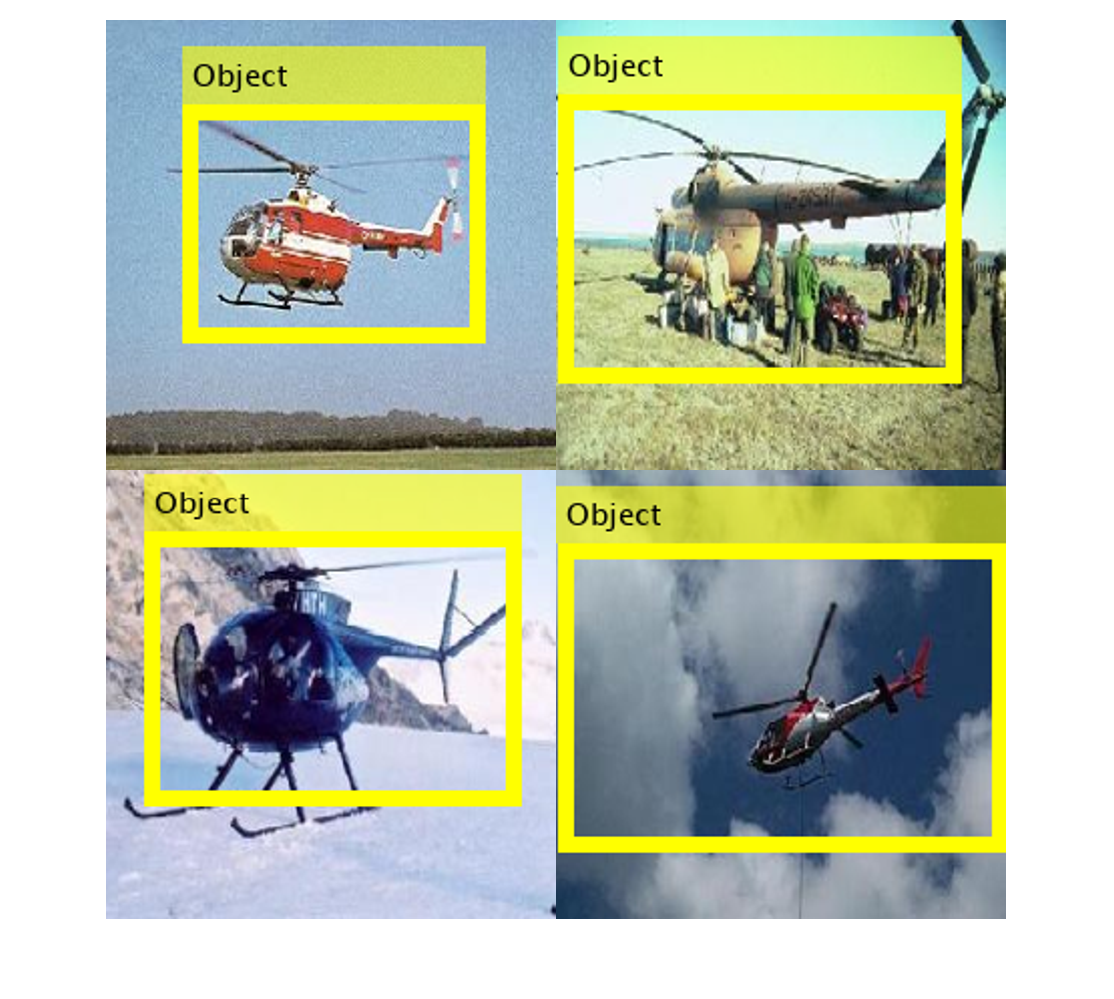

% Display the first four preprocessed images and predicted bounding boxes 
rgb = cell(4,1);
figure
for k = 1:4
    I = data{k,1};
    bbox = YPred(k,:);
    labels = 'Object';
    rgb{k} = insertObjectAnnotation(I,'rectangle',bbox,labels, ...
        'LineWidth',8,'FontSize',15);
end
montage(rgb)

Notice that the predicted bounding boxes do a reasonable job of detecting the objecct in the image on this validation data.

That is the end of the object detection part of the lab.

If you have further interest in learning about how to implement more sophisticated object detection and recognition systems that combine these two parts of the lab together (image recognition and detection) in one convolutional network, with the ability to detect multiple objects in an image, then you could check out Matlab's implementation of Yolo_v4 (You Only Look Once version 4): 

[https://uk.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html](https://uk.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html) 

#### 1.5.5 Helper function for image resizing

The function below is known as a helper function: a custom-function that performs a task that does not have a standard, in-built version in Matlab. In this case, the helper function performs image resizing AND corresponding resizing of the image bounding box for the image data store used in training the deep network.

function data = resizeImageAndLabel(data,targetSize)
    scale = targetSize./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize);
    data{2} = bboxresize(data{2},scale);
end